# 1229上课内容(1)

## Matlab进阶绘图

### fplot绘制一元函数，ezplot绘制二元函数，ezploar绘制极坐标函数

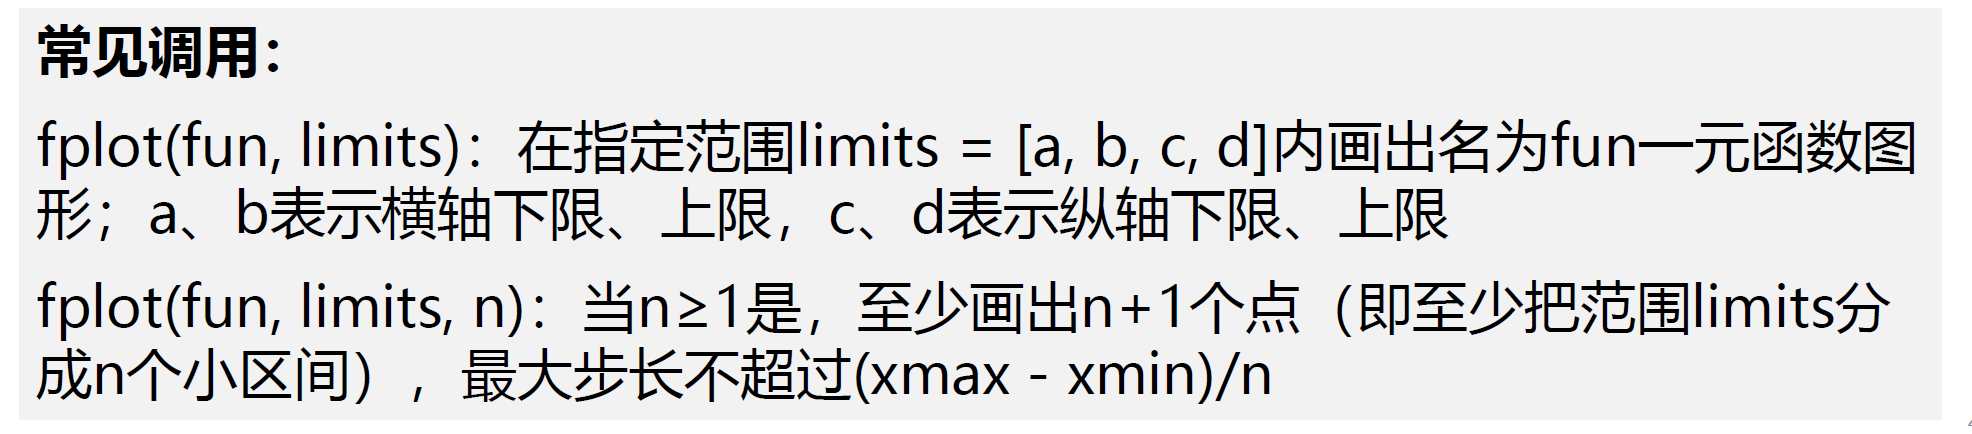

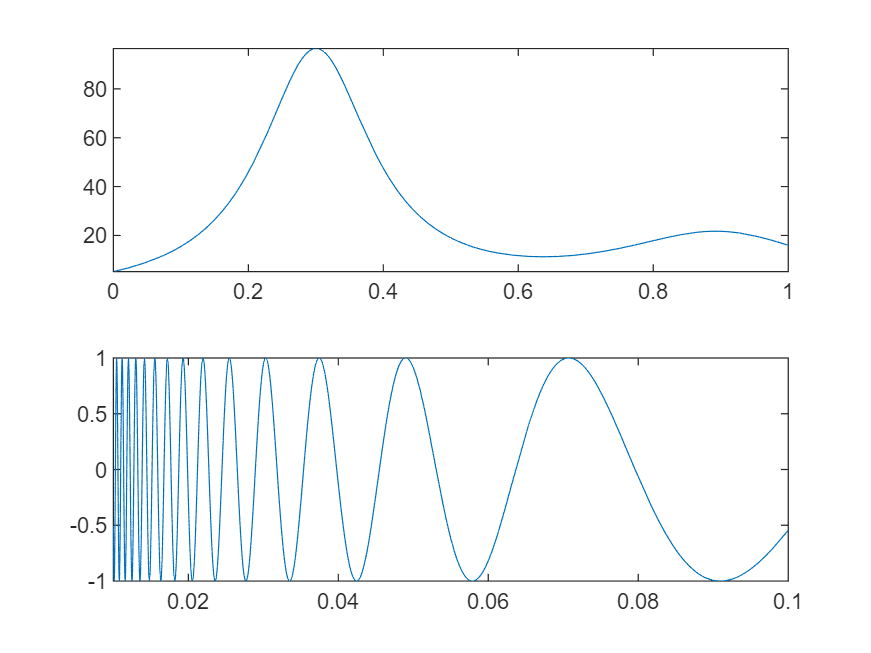

close all;
hmp = @humps;
subplot(2,1,1);
fplot(hmp,[0,1]);
sn = @(x)sin(1./x);
subplot(2,1,2);
fplot(sn,[.01,.1]);

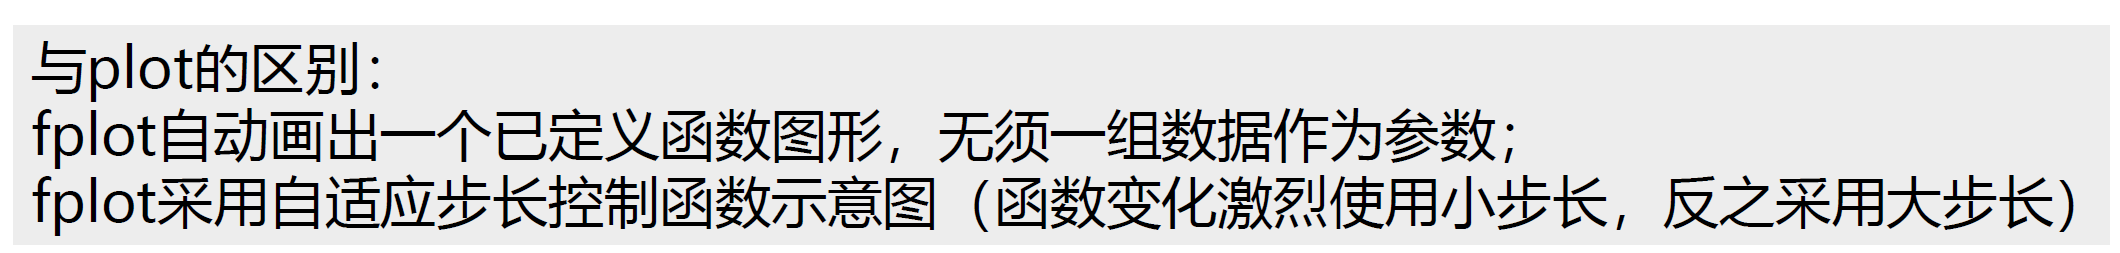

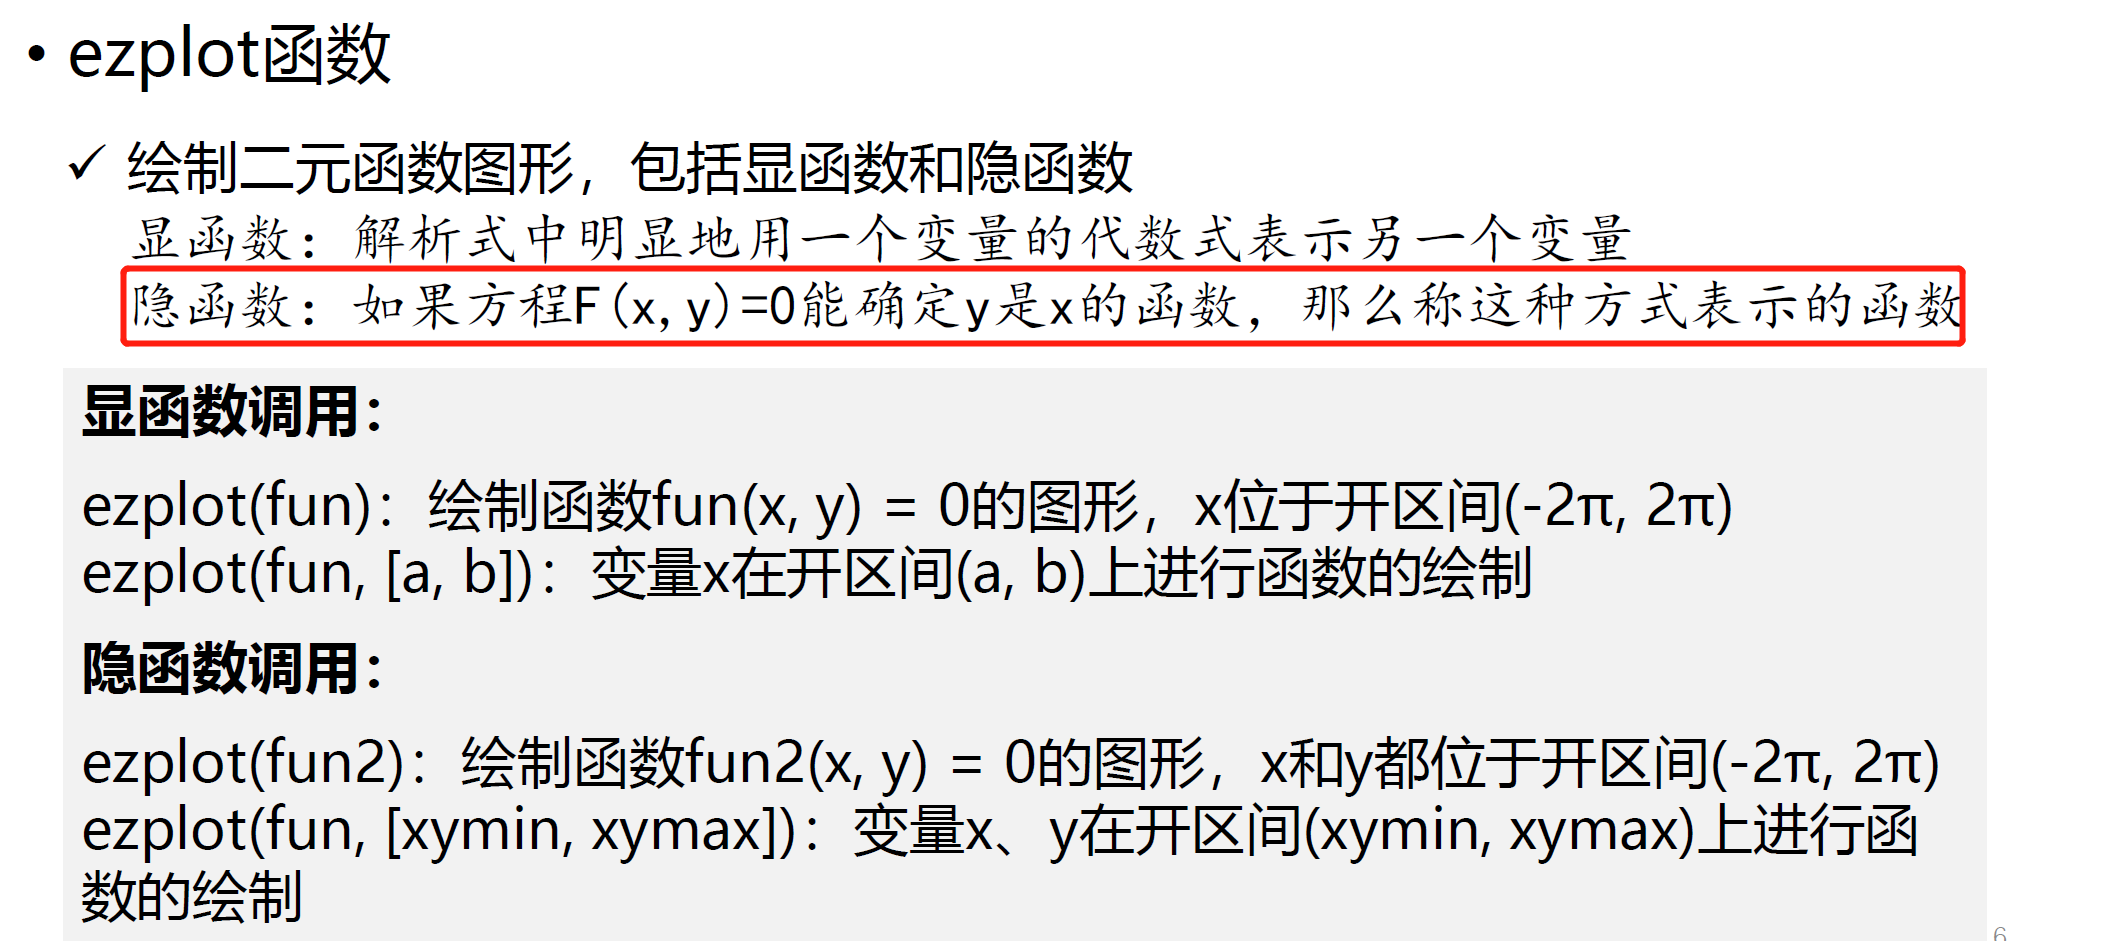

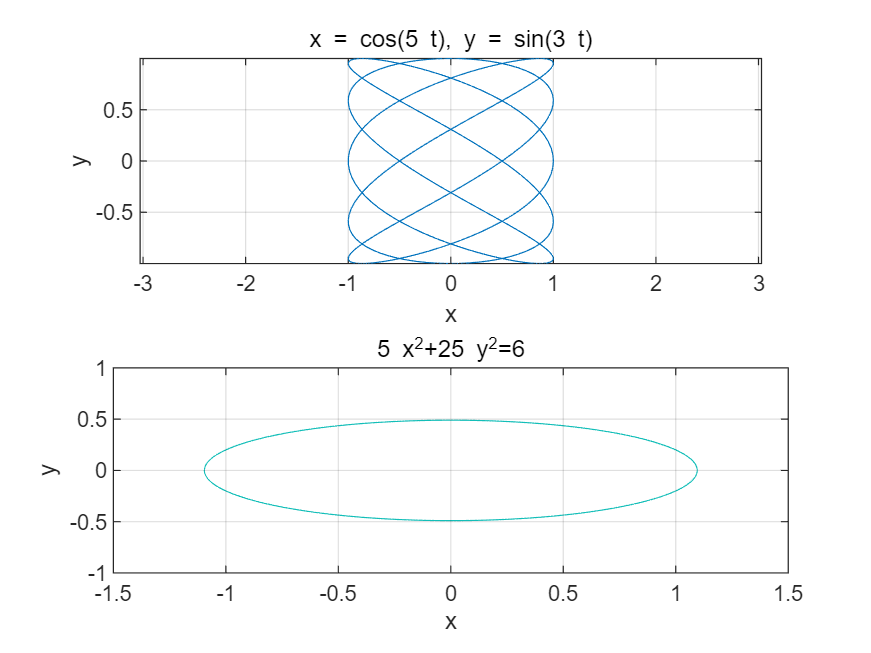

close all;
subplot(2,1,1);
ezplot('cos(5*t)','sin(3*t)',[0,2*pi]);
grid on;
subplot(2,1,2);
ezplot('5*x^2+25*y^2=6',[-1.5,1.5,-1,1]);
grid on;

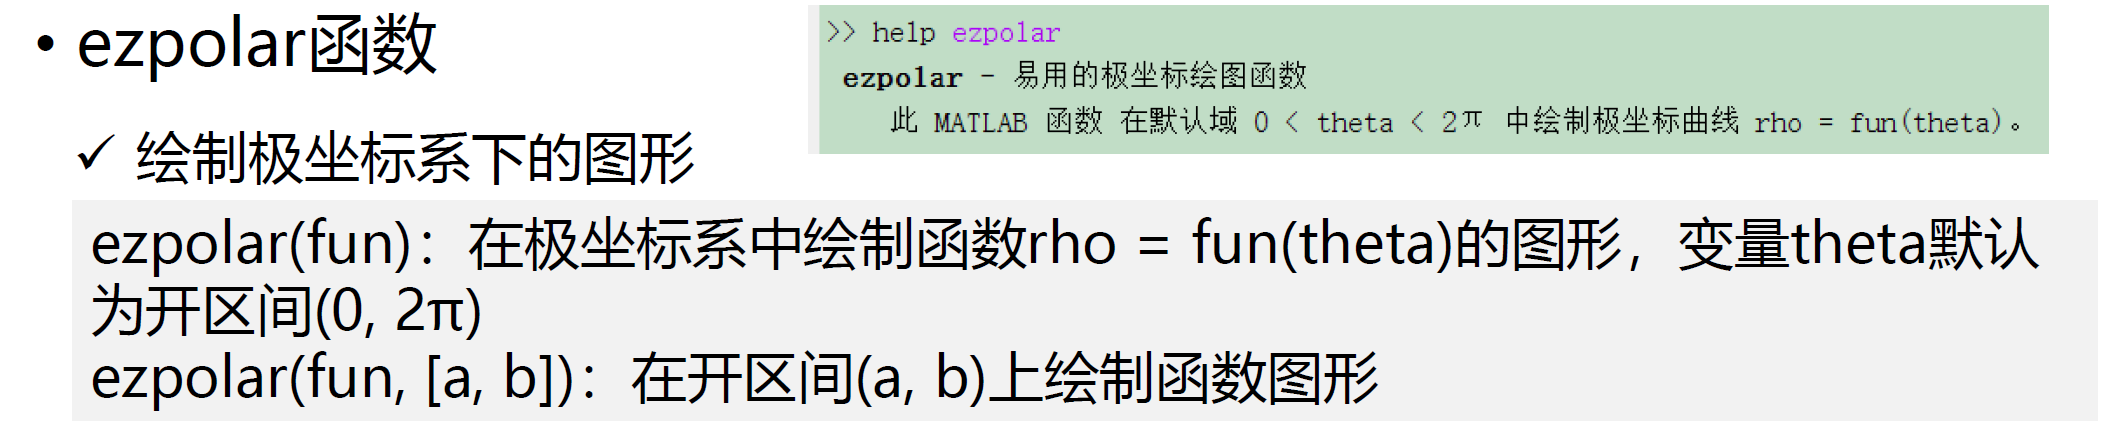

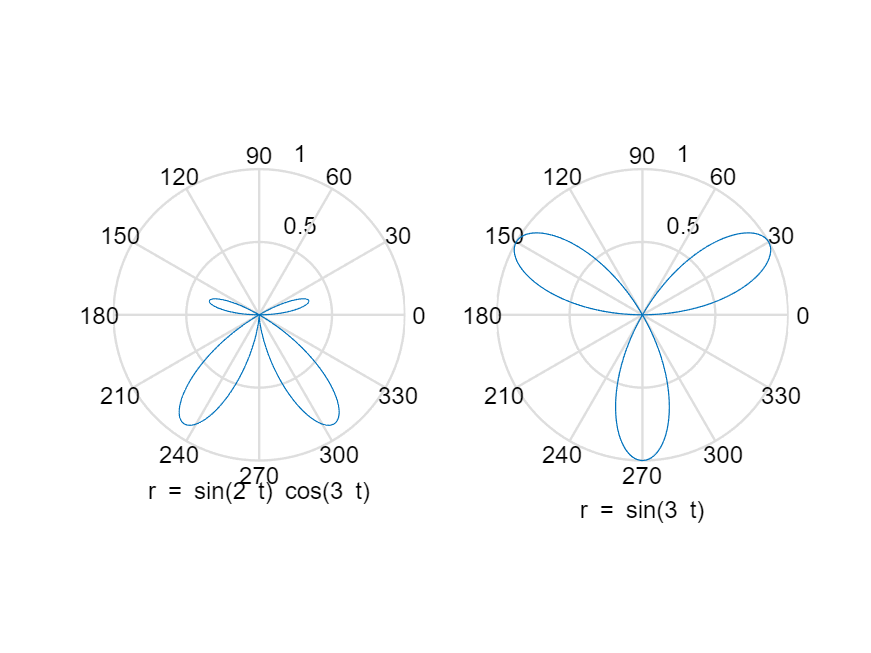

close all;
subplot(121);
ezpolar('sin(2*t).*cos(3*t)',[0,pi]); % 极坐标绘图
subplot(122);
ezpolar(@(t)sin(3*t),[0,2*pi]);

## 三维绘图功能介绍

### plot3

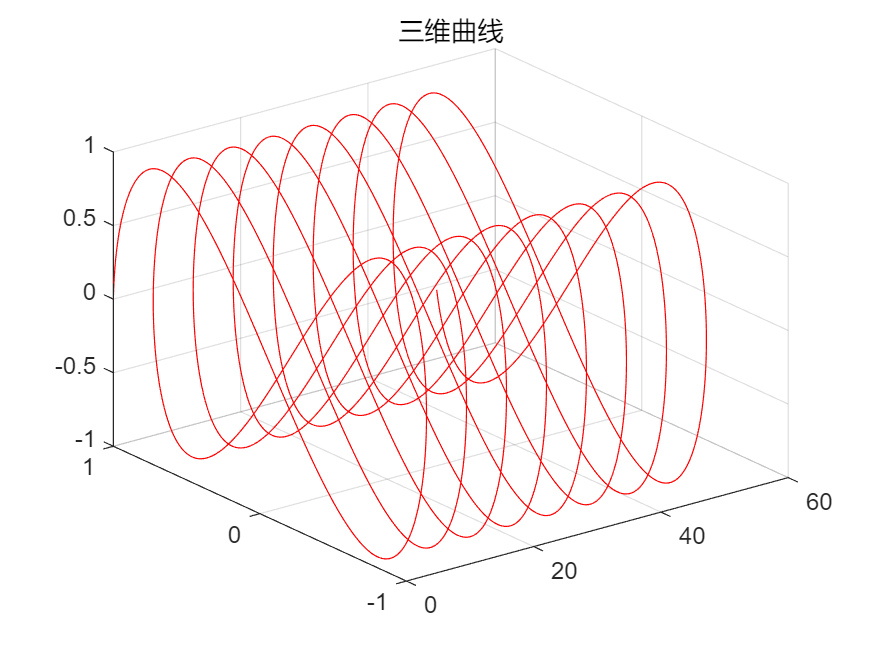

close all;
% 绘制参数方程的三维曲线
x = 0:0.01:50;
y = cos(x);
z = sin(2*x);
plot3(x,y,z,'r-');
grid on;
title('三维曲线');

### mesh

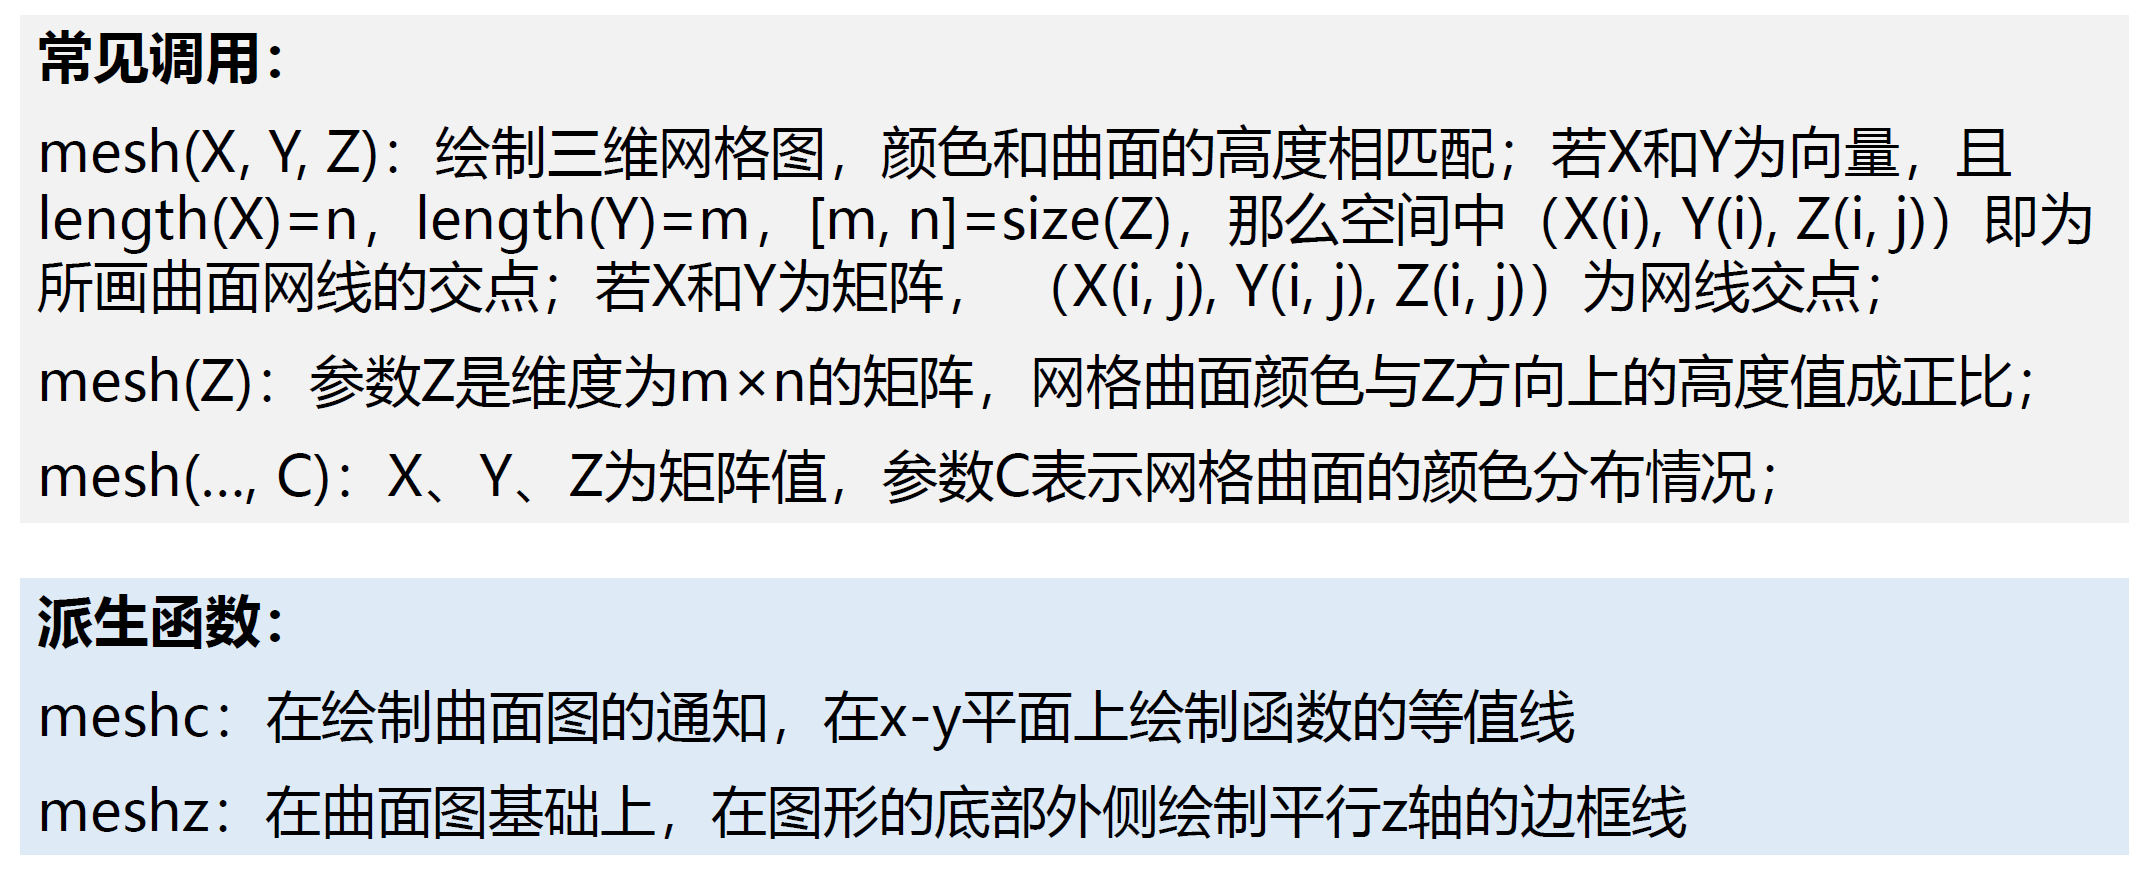

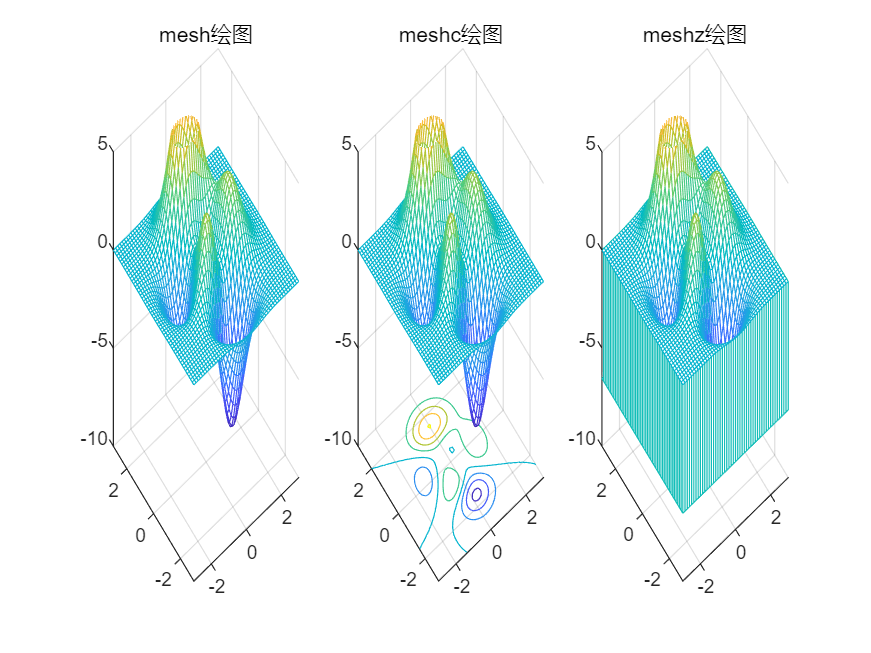

close all;
[X,Y] = meshgrid(-3:0.125:3);
Z = peaks(X,Y);
subplot(1,3,1);mesh(X,Y,Z);
title('mesh绘图');
axis([-3,3,-3,3,-10,5]);
subplot(1,3,2);meshc(X,Y,Z);
title('meshc绘图');
axis([-3,3,-3,3,-10,5]);
subplot(1,3,3);meshz(X,Y,Z);
title('meshz绘图');
axis([-3,3,-3,3,-10,5]);

set(gcf,'color','w');

### surf 三维曲面图

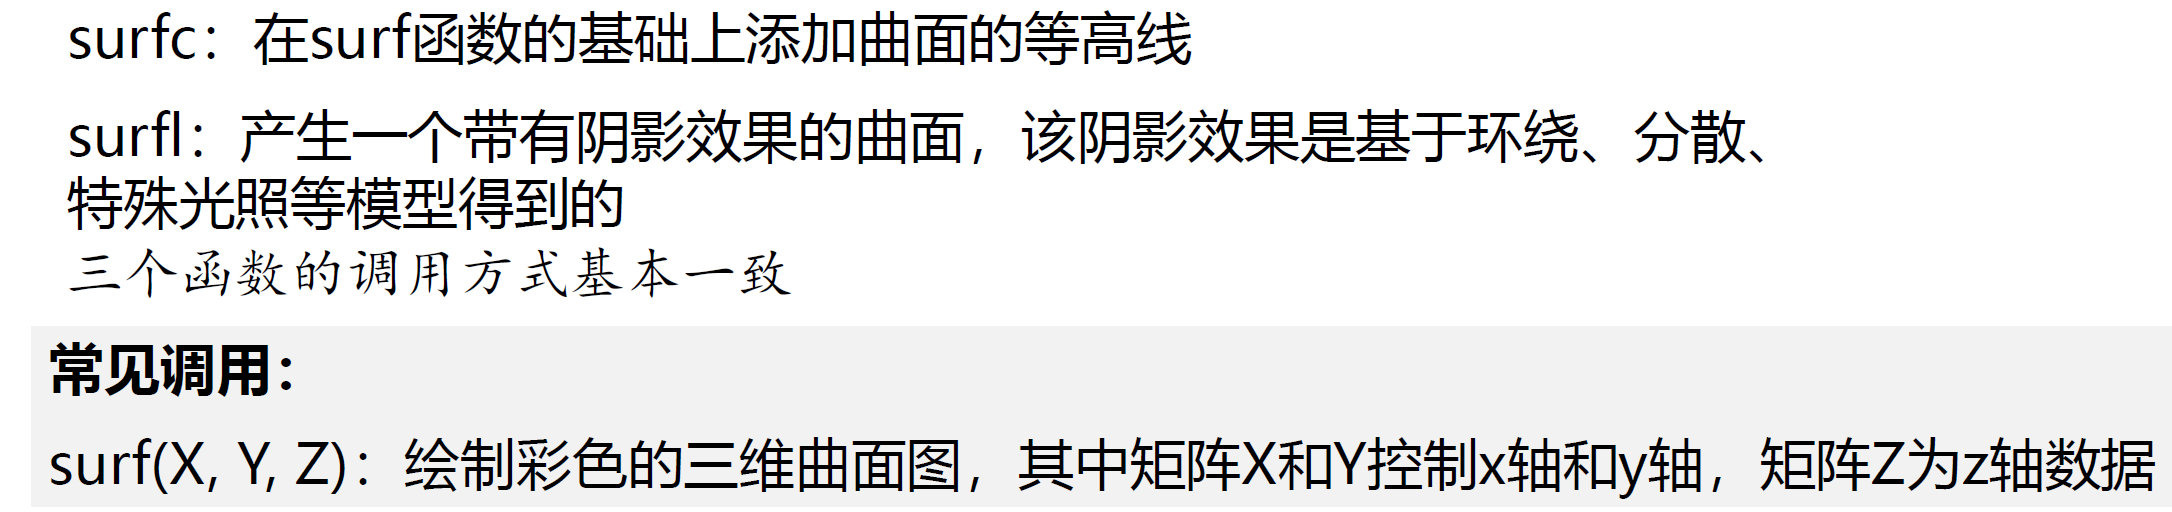

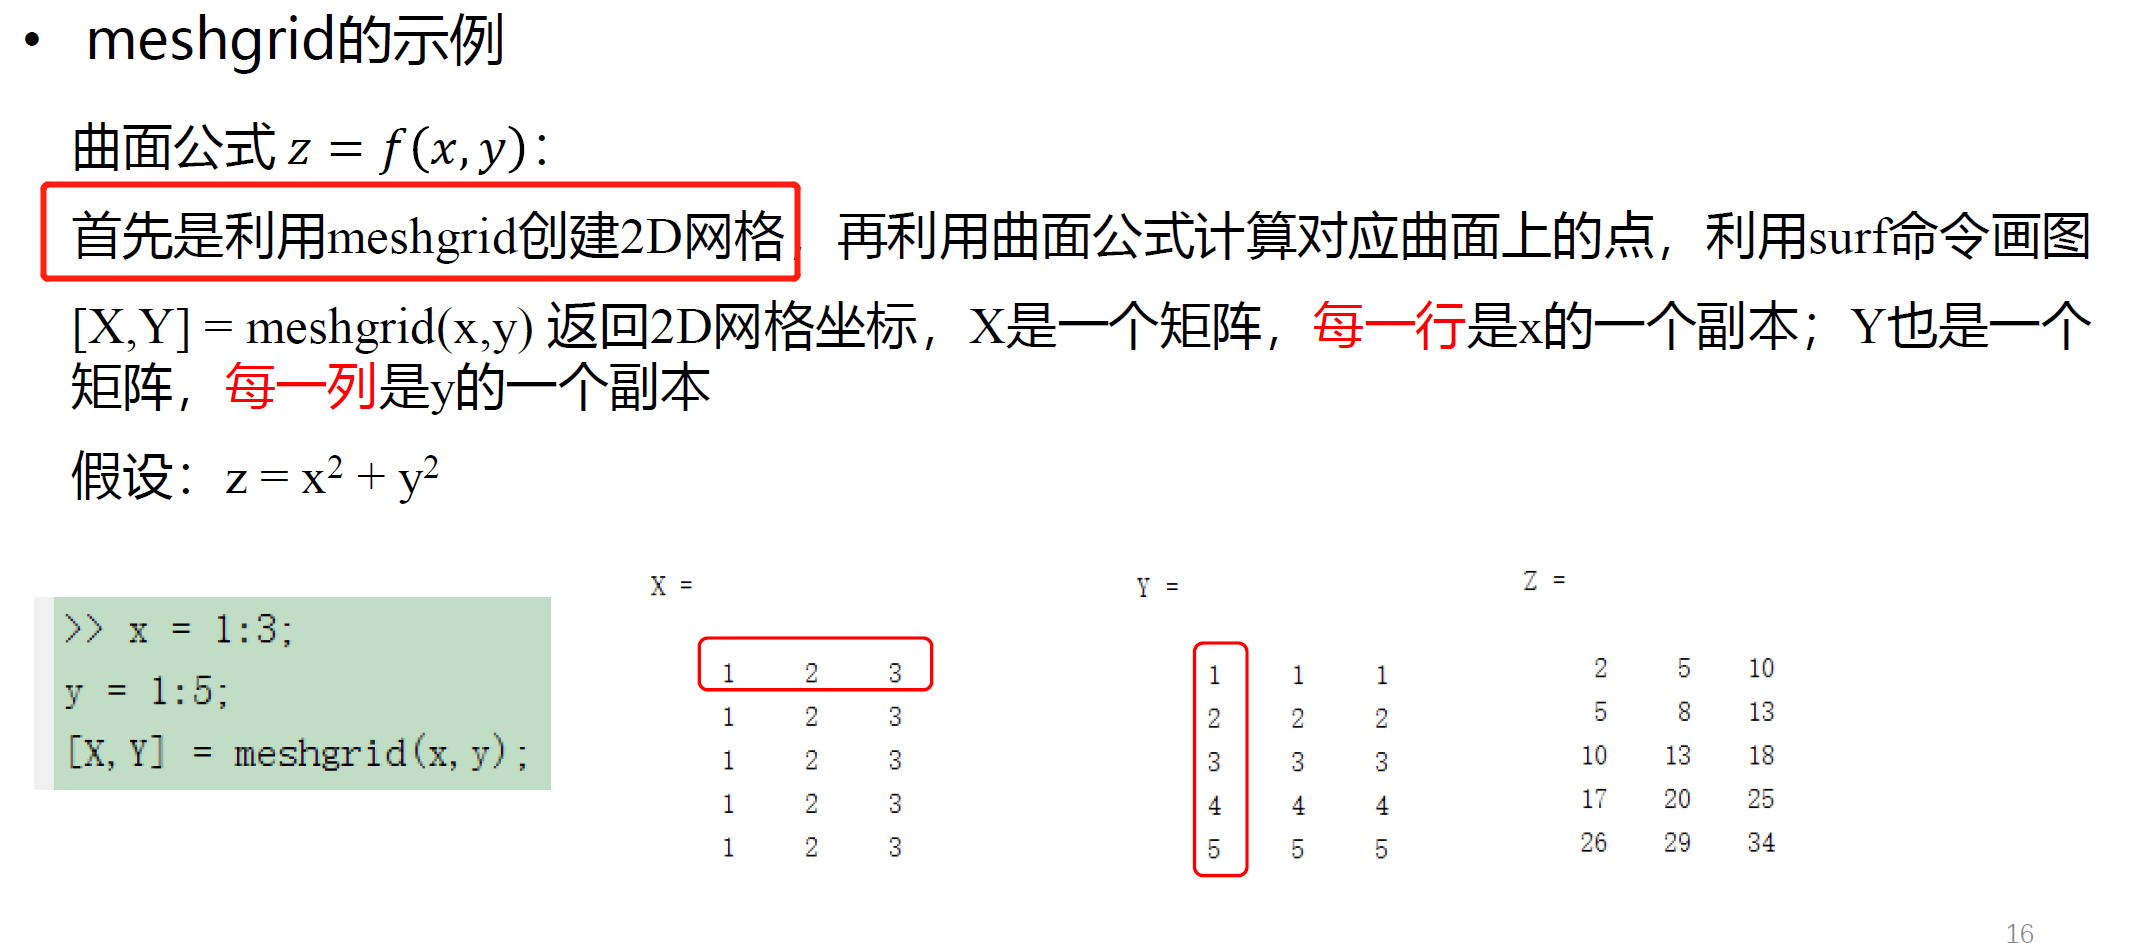

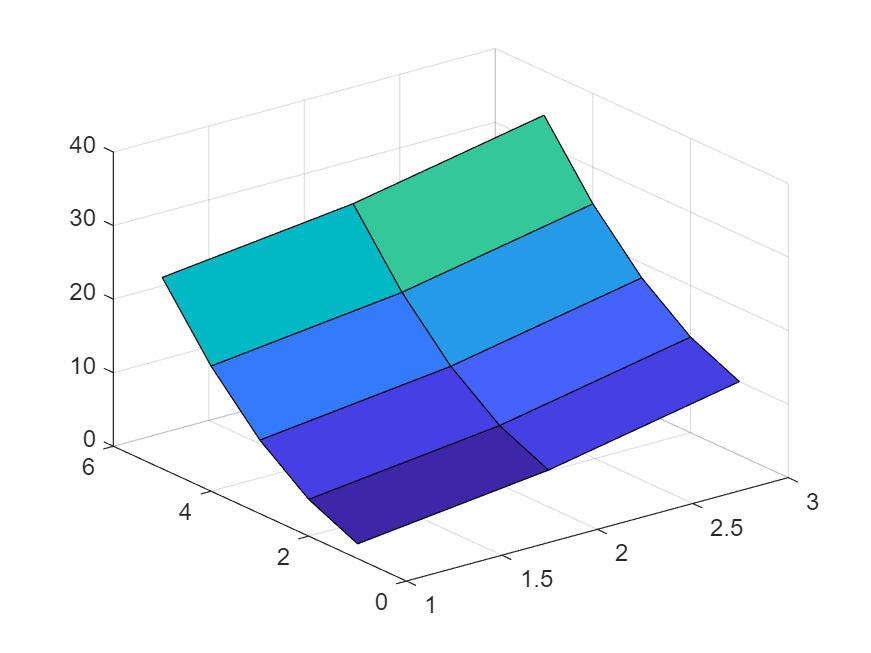

close all;
% 初步绘制
x = 1:3;
y = 1:5;
[X,Y] = meshgrid(x,y);
Z = X.^2 + Y.^2;
surf(X,Y,Z);

close all;

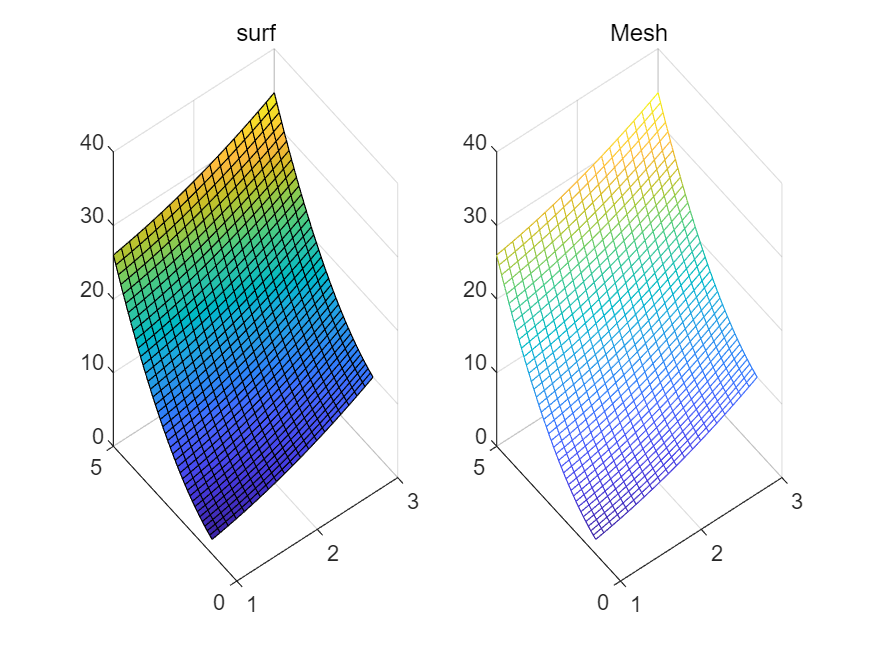

% 利用网格图表示
close all;
x = 1:0.1:3;  % 多一个0.1为步长，增大网格密集度
y = 1:0.1:5;
[X,Y] = meshgrid(x,y);
Z = X.^2 + Y.^2;
subplot(1,2,1);
surf(X,Y,Z);
title("surf");
subplot(1,2,2);
mesh(X,Y,Z);
title('Mesh');

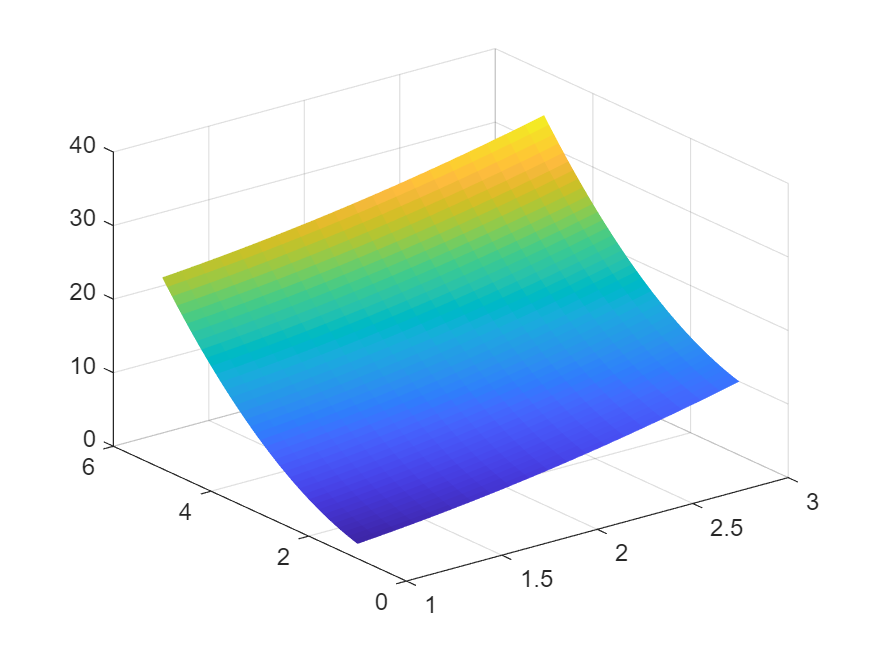

% 阴影效果
close all;
x = 1:0.1:3;
y = 1:0.1:5;
[X,Y] = meshgrid(x,y);
Z = X.^2 + Y.^2;
surf(X,Y,Z);
grid on;
shading flat;

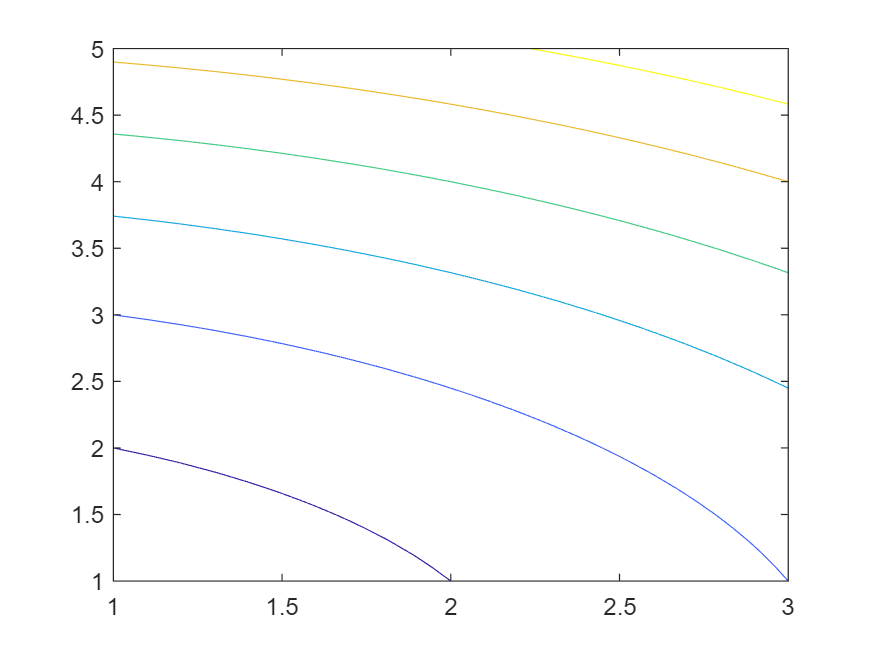

% 绘制等高线
close all;
x = 1:0.1:3;
y = 1:0.1:5;
[X,Y] = meshgrid(x,y);
Z = X.^2 + Y.^2;
contour(X,Y,Z);

### 更复杂的等高线绘制

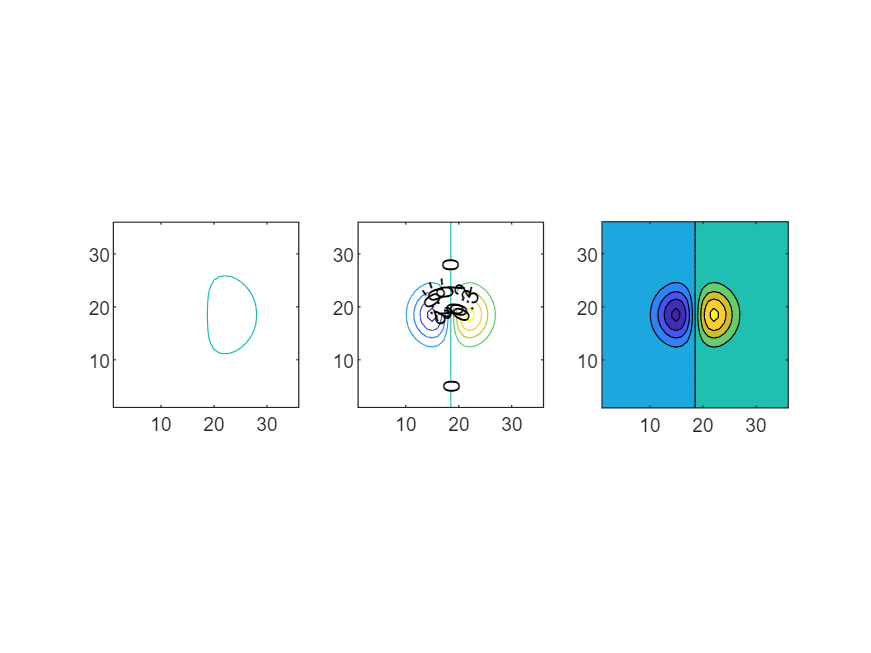

close all;
x = -3.5:0.2:3.5;
y = -3.5:0.2:3.5;
[X,Y] = meshgrid(x,y);
Z = X.*exp(-X.^2-Y.^2);
subplot(1,3,1);contour(Z,[-0.45,0.05,0.45]);axis("square");
subplot(1,3,2);[C,h] = contour(Z);clabel(C,h);axis("square");
subplot(1,3,3);contourf(Z);axis("square");

### 特殊的三维图形

**针对直方图，圆柱图，饼图进行三维展示**

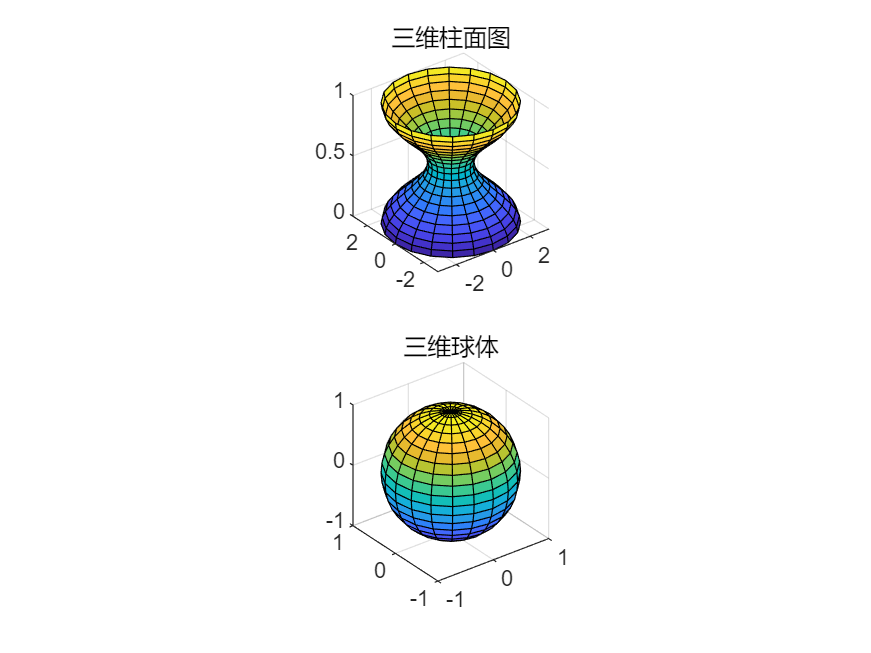

close all;
t = 0:pi/10:2*pi;
[X1,Y1,Z1] = cylinder(2+cos(t));
subplot(2,1,1);surf(X1,Y1,Z1);
axis("square");title("三维柱面图");
subplot(2,1,2);sphere;
axis equal;title('三维球体');

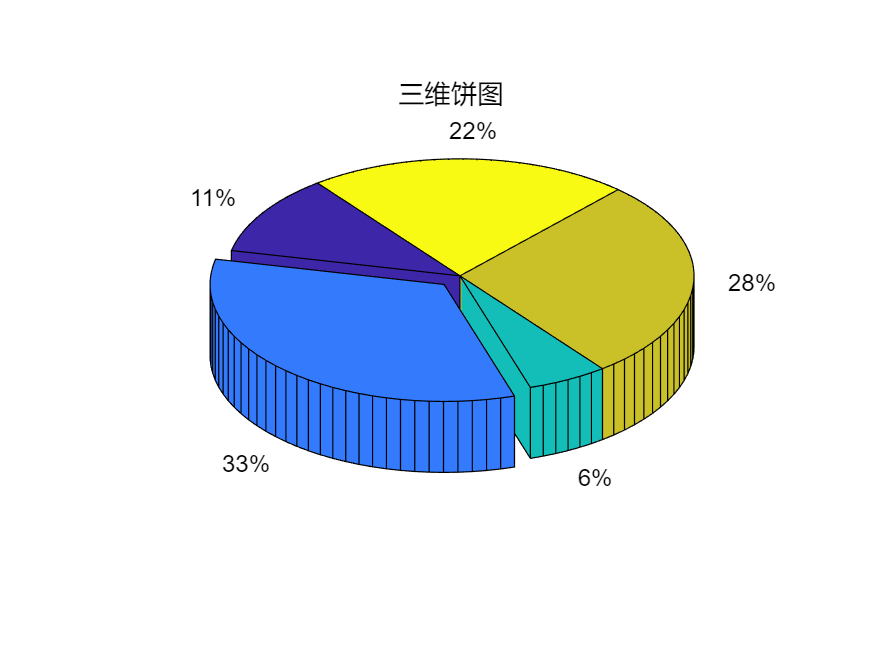

close all;
x1 = [1,3,0.5,2.5,2];
explode = [0,1,0,0,0];
pie3(x1,explode);
title('三维饼图');axis equal;

**三维填充图和三维彩带图**

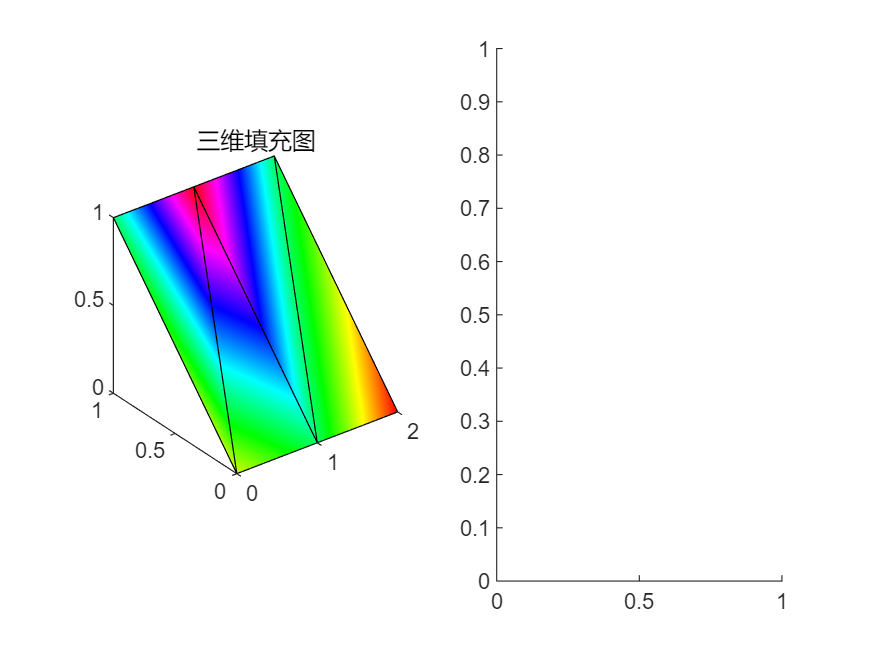

函数或变量 'ribbon3' 无法识别。

close all;
X2 = [0,1,1,2;1,1,2,2;0,0,1,1];
Y2 = [1,1,1,1;1,0,1,0;0,0,0,0];
Z2 = [1,1,1,1;1,0,1,0;0,0,0,0];
C = [0.5,1,1,0.5;
    1,0.5,0.5,0.1667;
    0.333,0.333,0.5,0.5];
subplot(1,2,1);fill3(X2,Y2,Z2,C);
colormap hsv;
title('三维填充图');axis('square');
[x2,y2] = meshgrid(-3,0.5:3,-3:0.1:3);
z2 = peaks(x2,y2);
subplot(1,2,2);ribbon(y2,z2);

colormap hsv;
title('三维彩带图');axis equal;

**三维为向量场图**

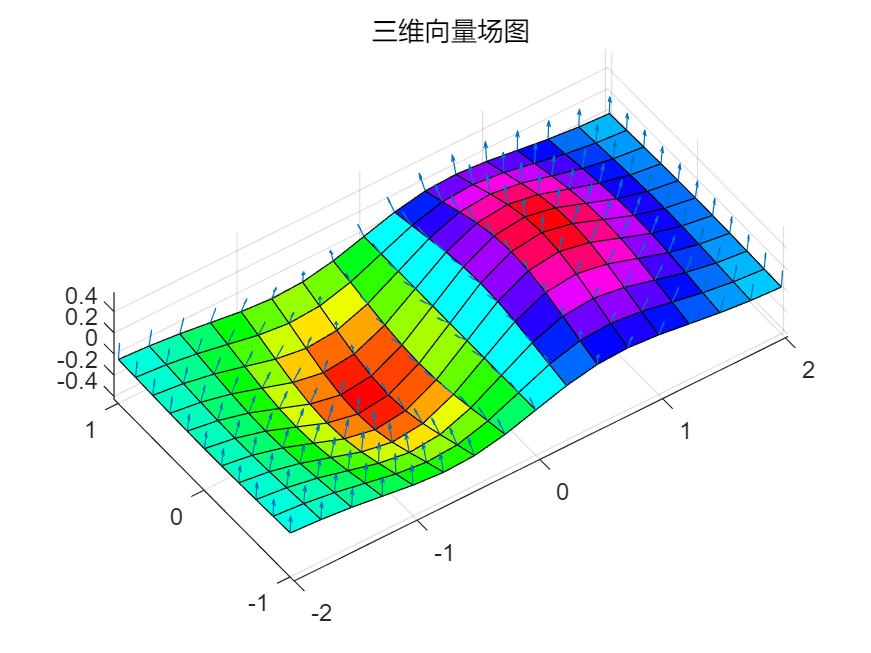

close all;
[X3,Y3] = meshgrid(-2:0.25:2,-1:0.2:1);
Z3 = X3.*exp(-X3.^2-Y3.^2);
[U,V,W] = surfnorm(X3,Y3,Z3);
quiver3(X3,Y3,Z3,U,V,W,0.5);
hold on;
surf(X3,Y3,Z3);
colormap hsv;
view(-35,45);
title('三维向量场图');axis equal;

set(gcf,'color','w'); % 设置背景色为白色

## 绘图与数学

### 画心形曲线

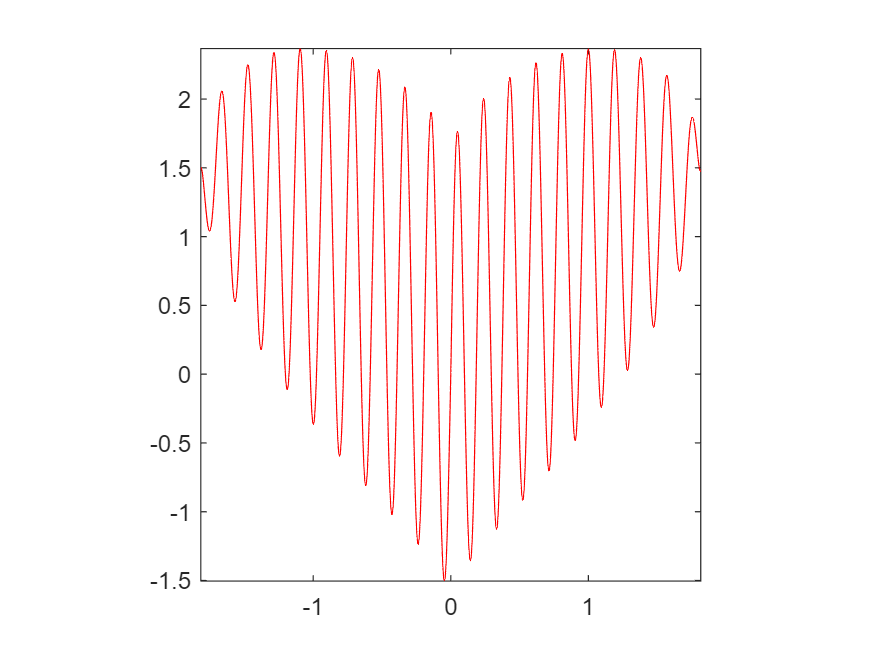

% 绘制方法1
close all;
f = @(x)nthroot(x.^2,3)+0.9*sqrt(3.3-x.^2).*sin(33*x);
fplot(f,[-1,1]*sqrt(3.3),'-r');
axis equal;

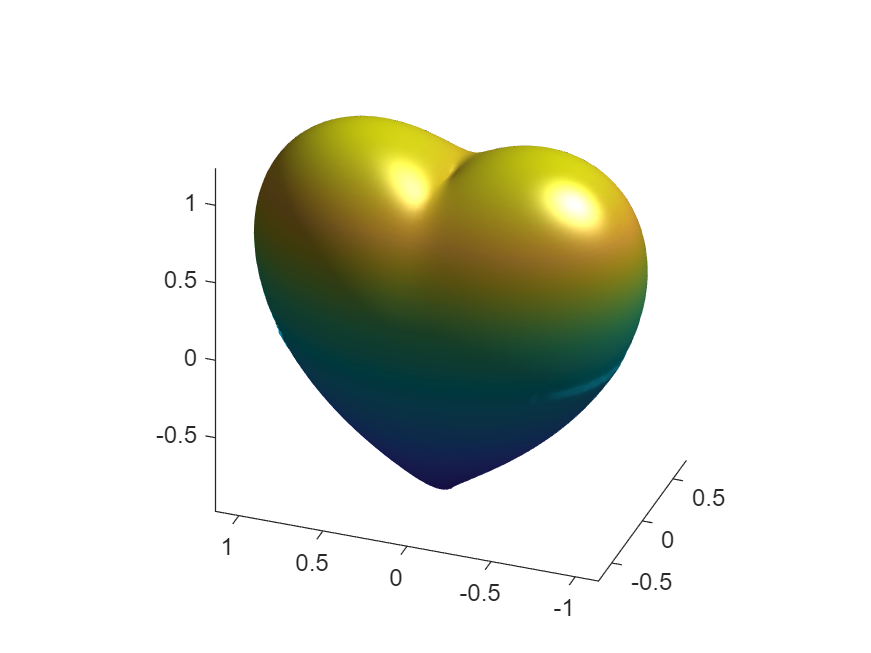

% 绘制方法2
[X,Y,Z] = meshgrid(linspace(-1.5,1.5));
F = @(x,y,z)(2*x.^2+y.^2+z.^2-1).^3-x.^2.*z.^3/10-y.^2.*z.^3;
figure;
isosurface(X,Y,Z,F(X,Y,Z),0,Z);
axis equal tight;
view(-70,30);

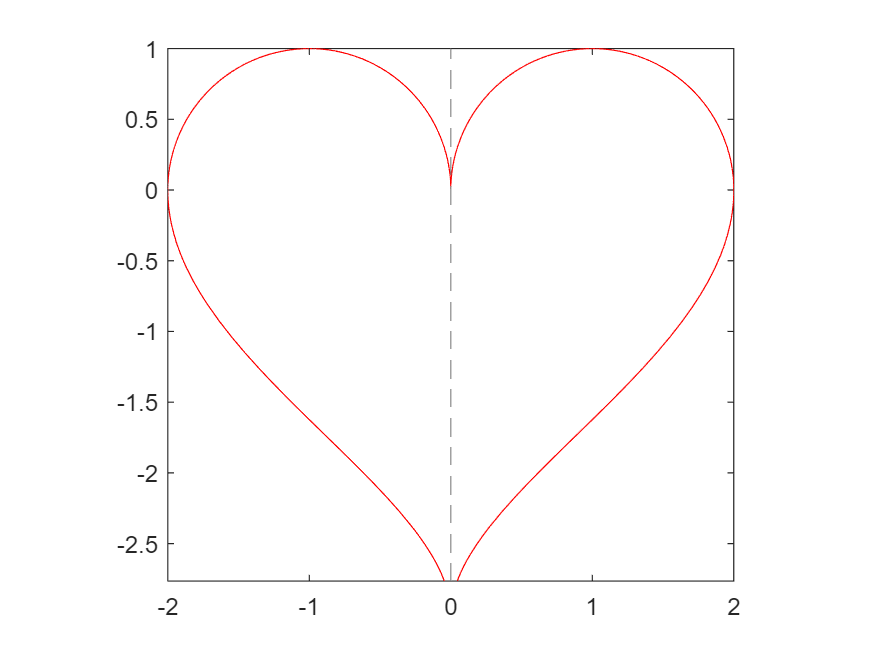

% 修改view的参数值能够改变试视图的方向
% 绘制方法3
g = @(x)[sqrt(1-(abs(x)-1).^2),-3*sqrt(1-sqrt(abs(x)/2))];
figure;
fplot(g,[-2,2],'r');
axis equal;

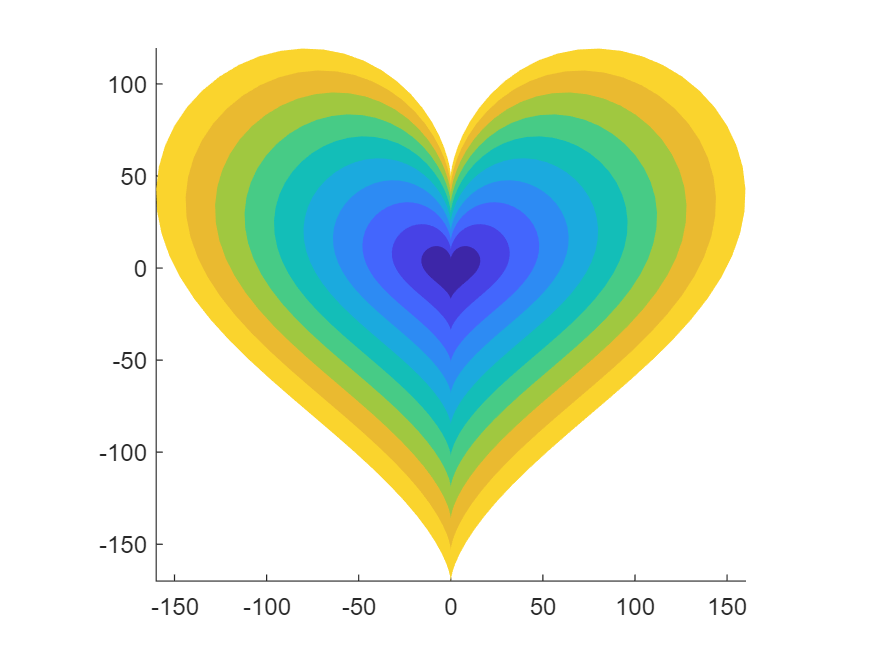

% 绘制方法4
[t,r] = meshgrid(linspace(-pi,pi),0:10);
x = r.*16.*sin(t).^3;
y = r.*(13*cos(t)-5*cos(2*t)-2*cos(3*t)-cos(4*t));
figure;
surf(x,y,r,'EdgeColor','none');view(2);
axis equal tight;
grid off;

## 高级绘图

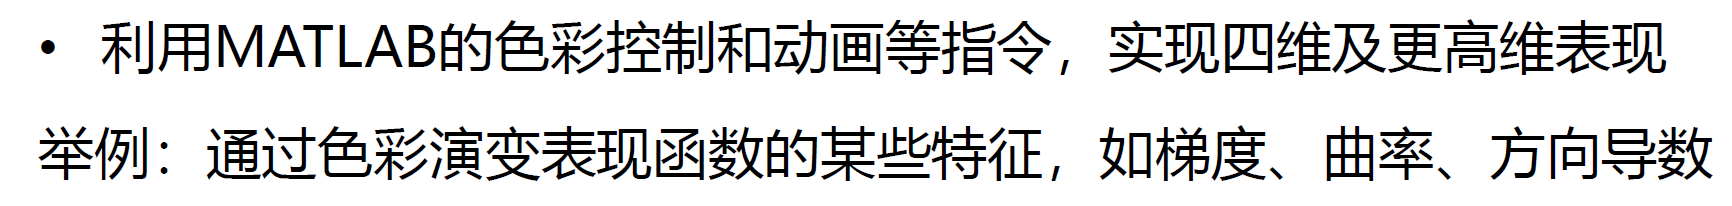

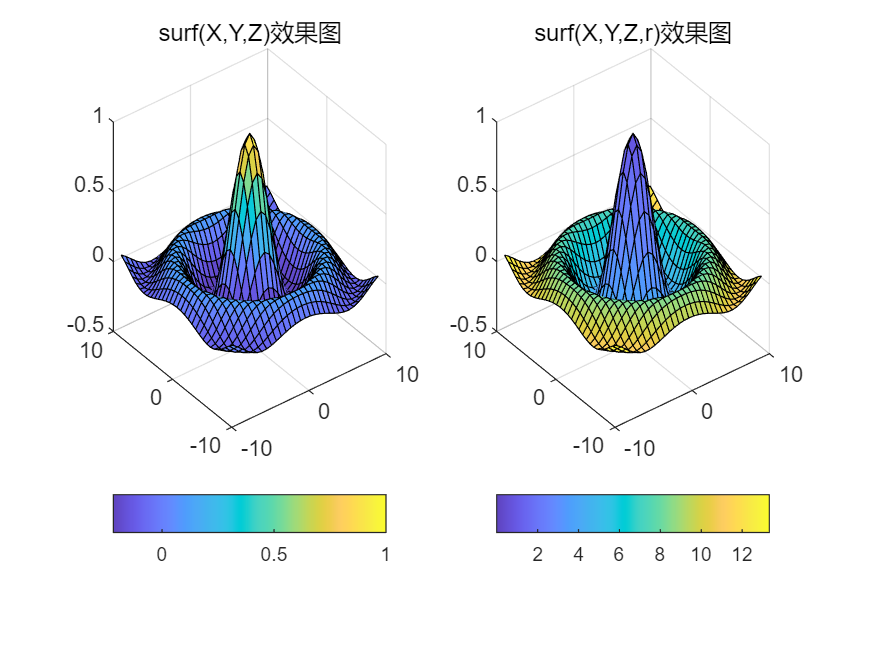

close all;
x = 3*pi*(-1:1/15:1);y=x;
[X,Y] = meshgrid(x,y);
r = sqrt(X.^2+Y.^2)+eps;
Z = sin(r)./r;
[dx,dy] = gradient(Z); % 计算对r全导数
dz = sqrt(dx.^2+dy.^2);
dz2 = del2(Z); % 计算曲率
subplot(1,2,1);surf(X,Y,Z);
title('surf(X,Y,Z)效果图');
shading faceted,colorbar('horiz');
brighten(0.3);
subplot(1,2,2);surf(X,Y,Z,r);
title('surf(X,Y,Z,r)效果图');
shading faceted,colorbar('horiz');

set(gcf,'color','w');

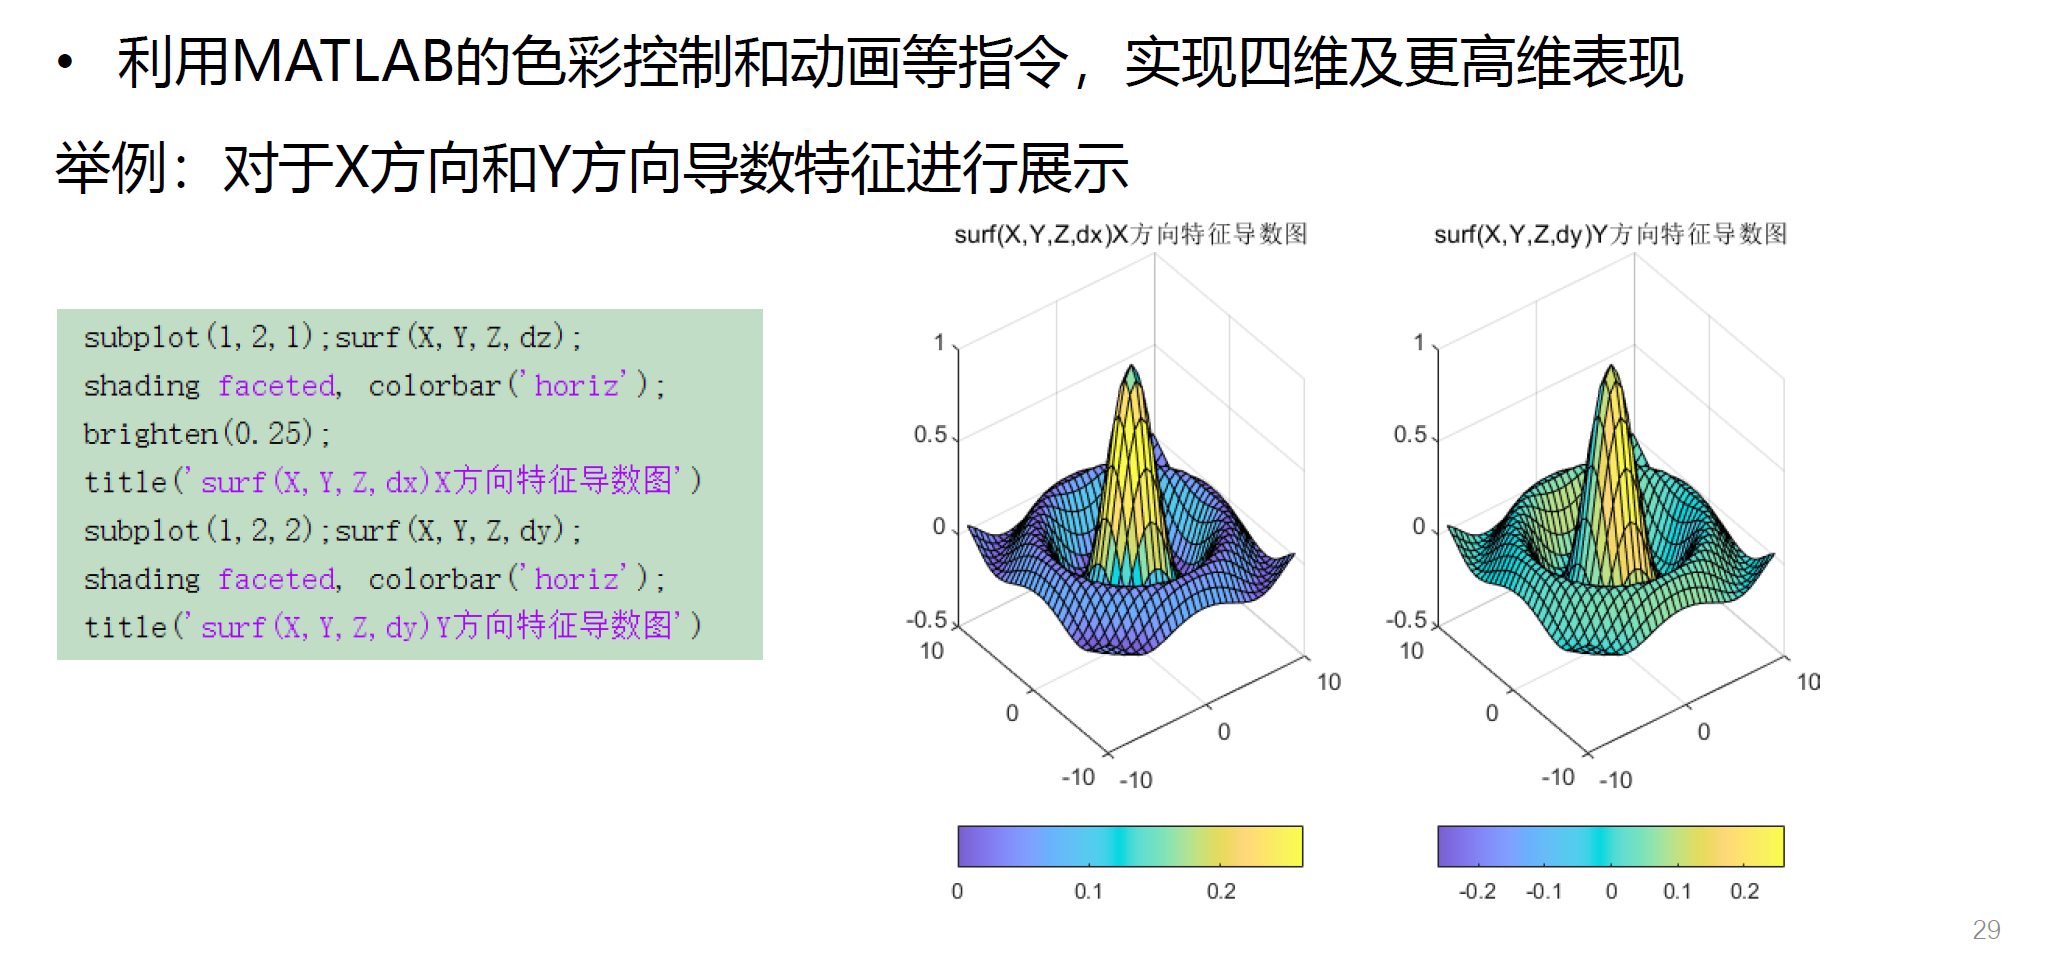

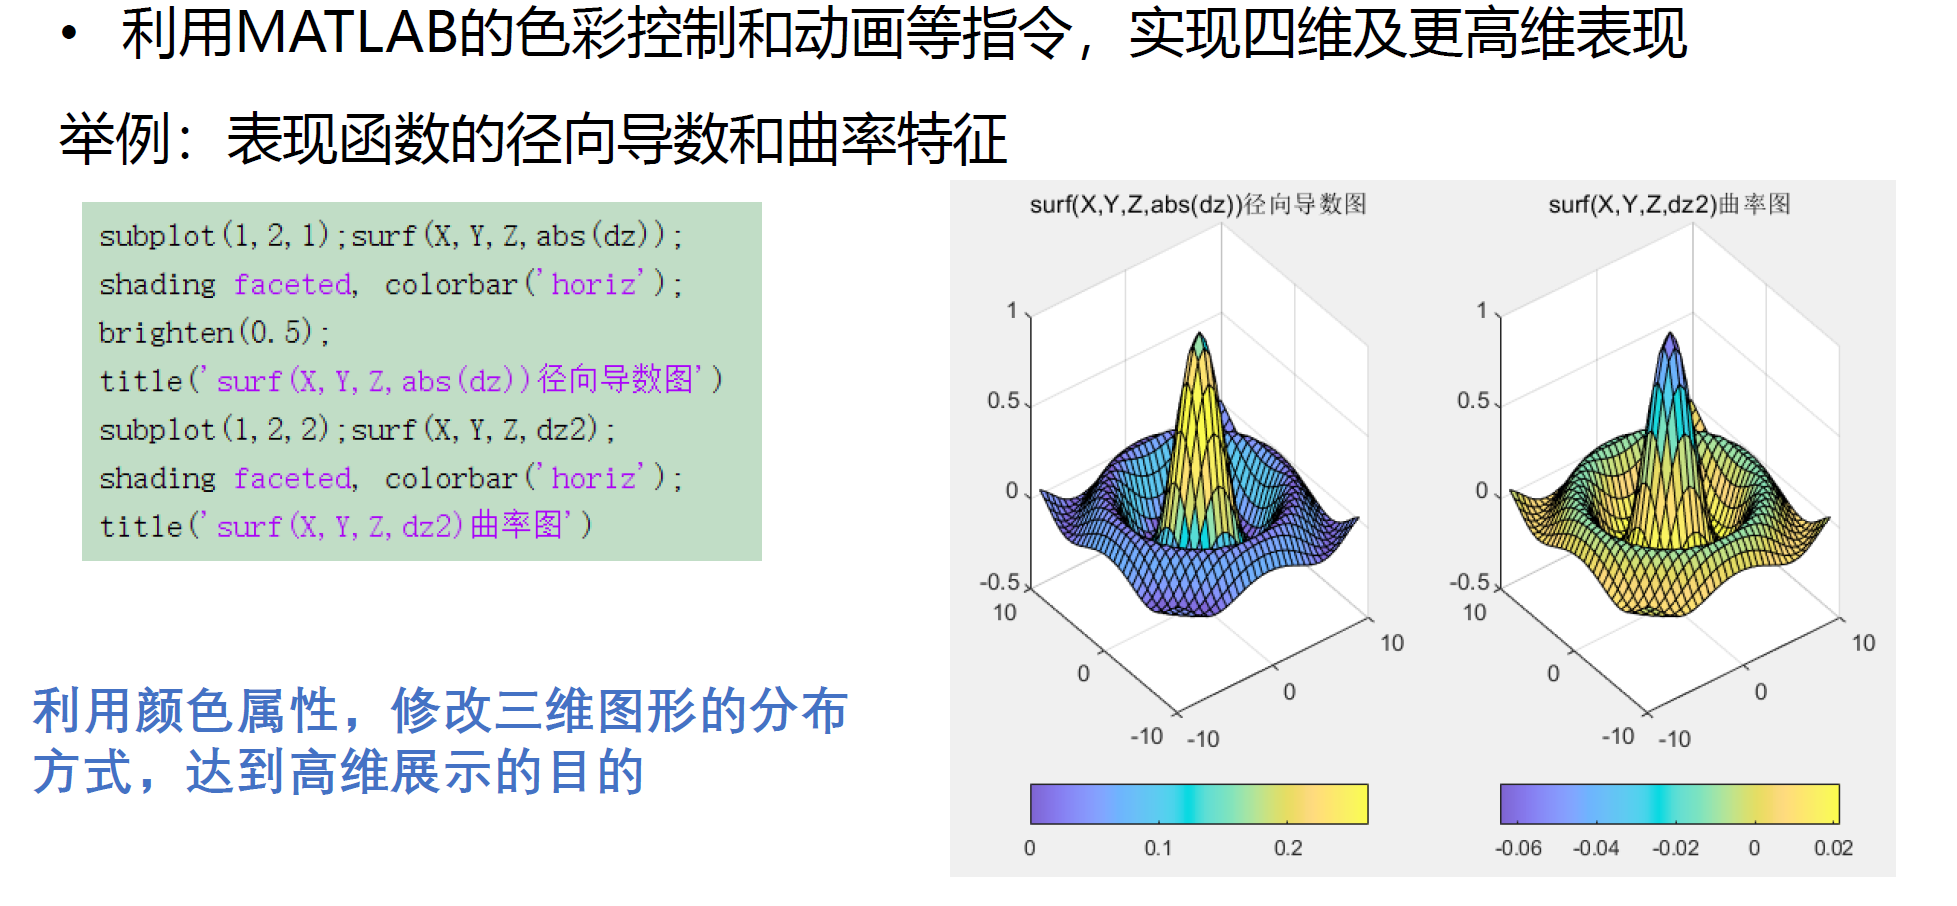

## slice 和 contourslice 切片图和切片等位线图

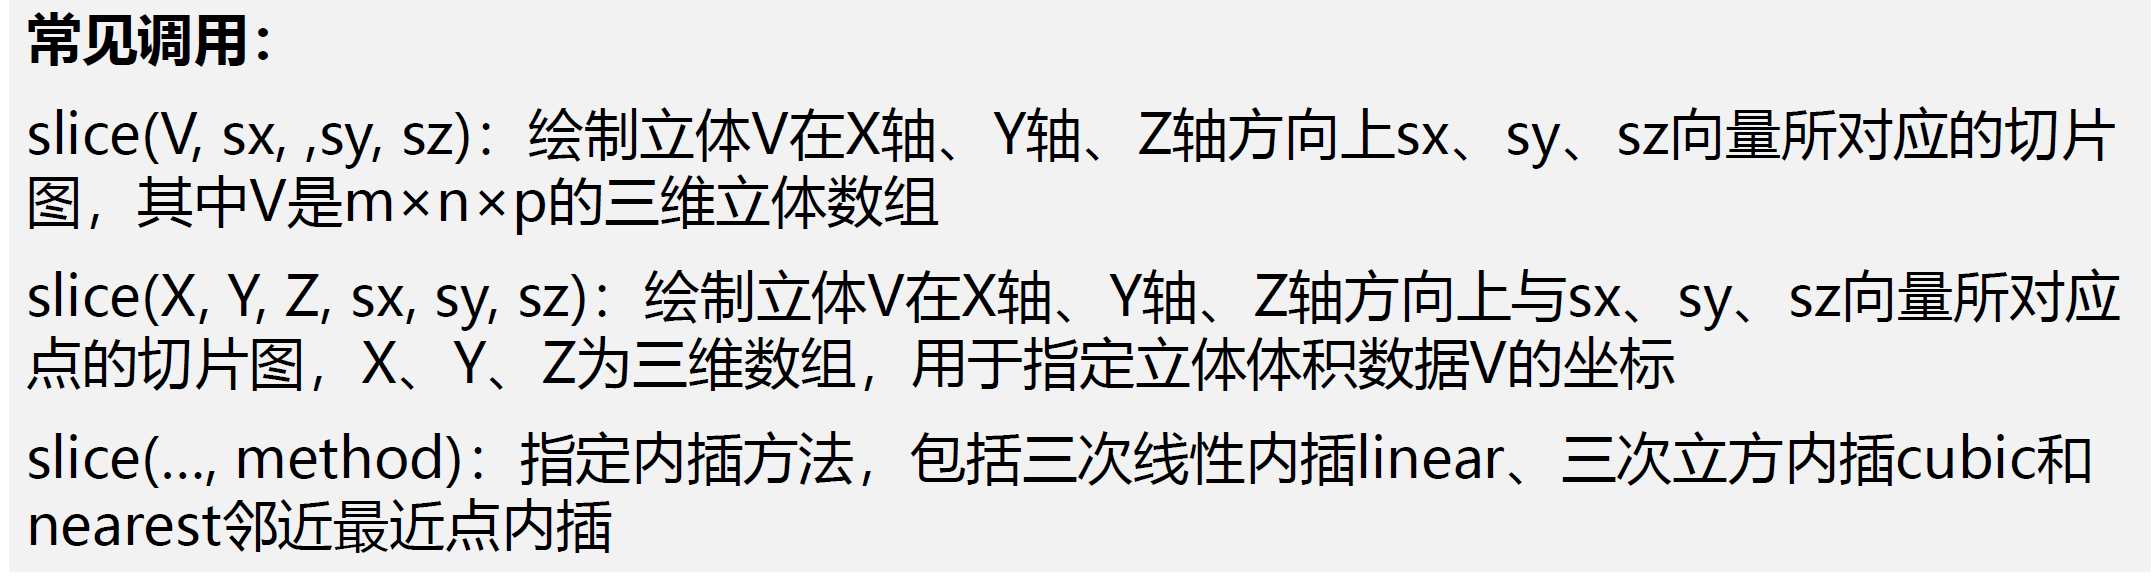

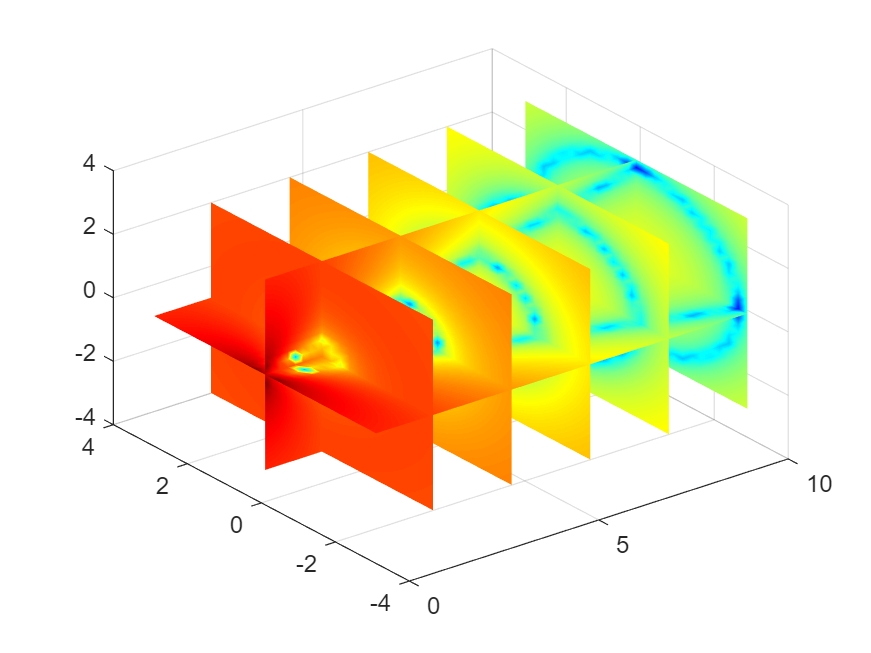

% 利用slice函数绘制水体中水下射流速度数据flow (flow是matlab提供的数据)
close all;
[X,Y,Z,V] = flow; % 取四个(50x25x25)的射流数据矩阵,V是射流速度
x1 = min(min(min(X))); x2 = max(max(max(X))); % 取X坐标上下限
y1 = min(min(min(Y))); y2 = max(max(max(Y))); % 取Y坐标上下限
z1 = min(min(min(Z))); z2 = max(max(max(Z))); % 取Z坐标上下限
sx = linspace(x1+1.5,x2,5); % 确定5个垂直X轴的切面坐标
sy = 0; % 在y=0处，取垂直y轴的切面
sz = 0; % 在z=0处，取垂直z轴的切面
slice(X,Y,Z,V,sx,sy,sz);
view([-38,38]);shading interp;
colormap jet;

set(gcf,'color','w');

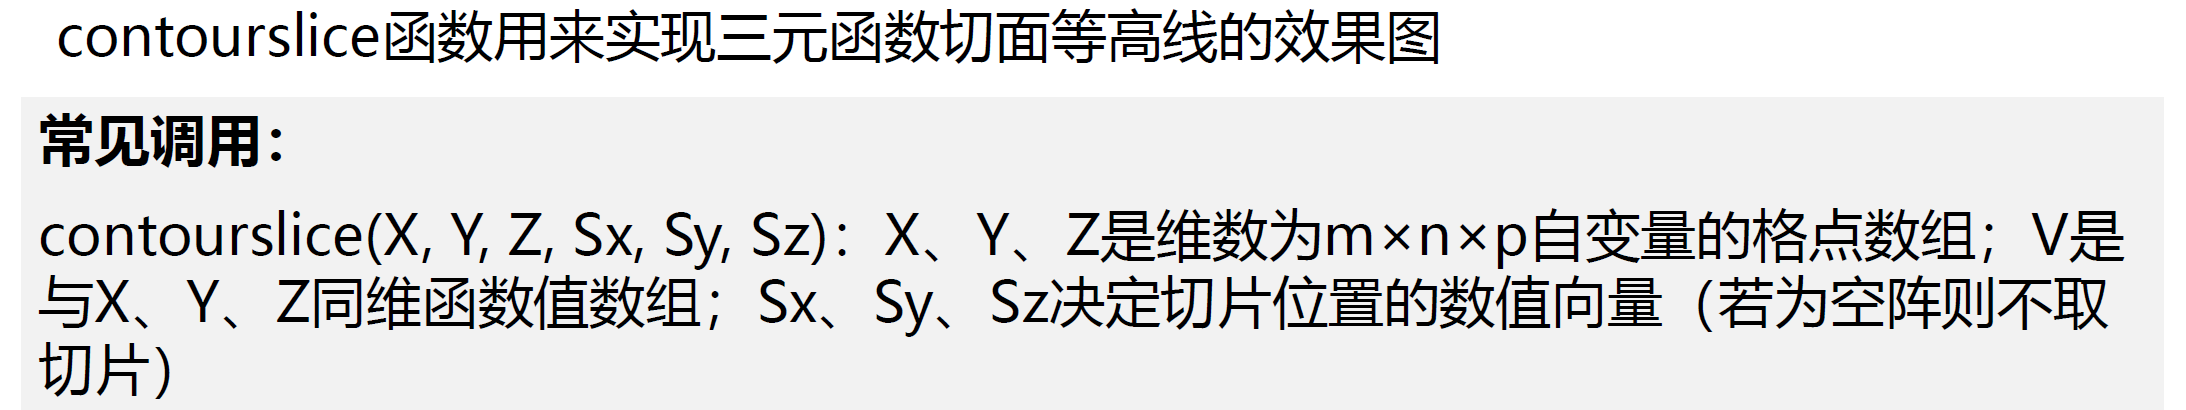

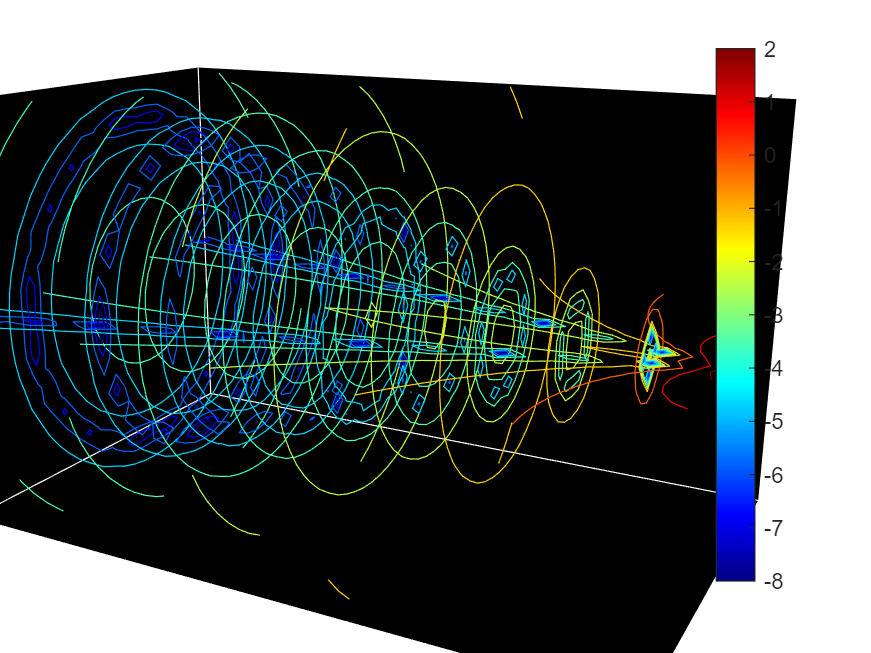

close all;
[x,y,z,v] = flow;
h = contourslice(x,y,z,v,[1:9],[],[0],linspace(-8,2,10));
axis([0,10,-3,3,-3,3]);daspect([1,1,1]);
camva(24);camproj perspective;
campos([-3,15,5]);
set(gcf,'Color',[0.5,0.5,0.5],"Renderer",'zbuffer');
set(gca,'Color','black','XColor','white','YColor','white','ZColor','white');
colormap jet;colorbar;
box on;
set(gcf,'color','w');